# ** Получение данных из .nc файла**

sst = ncread("A2017348114000.L2_LAC_SST.nc", 'geophysical_data/sst');
latitude = ncread("A2017348114000.L2_LAC_SST.nc", 'navigation_data/latitude');
longitude = ncread("A2017348114000.L2_LAC_SST.nc", 'navigation_data/longitude');

# **Создание векторов долготы и широты и матрицы температур**

n = 1000;
picture = zeros(n);

t = reshape(ss',1,[]);
lon = linspace(min(min(longitude)), max(max(longitude)), n);
lat = linspace(min(min(latitude)), max(max(latitude)), n);


for i = 1: 1354
    for j = 1: 2030
        [v_lon, ind_x] = min(abs(lon - longitude(i, j)));
        [v_lat, ind_y] = min(abs(lat - latitude(i, j)));
        picture(ind_y, ind_x) = sst(i, j);
    end
end

# **Построение графика **

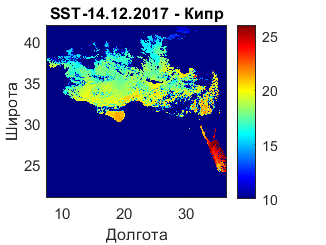

plot = subplot(1, 1, 1);
imagesc(lon, lat, picture);
set(gca, 'YDir', 'normal');
colormap(plot, 'jet');
caxis([10, 26]);
colorbar;
xlabel('Долгота');
ylabel('Широта');
title('SST-14.12.2017 - Кипр');
saveas(plot, 'Temperature_Kipr.png')